## Broadband has no phase

This demo illustrates how broadband signals have no phase

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

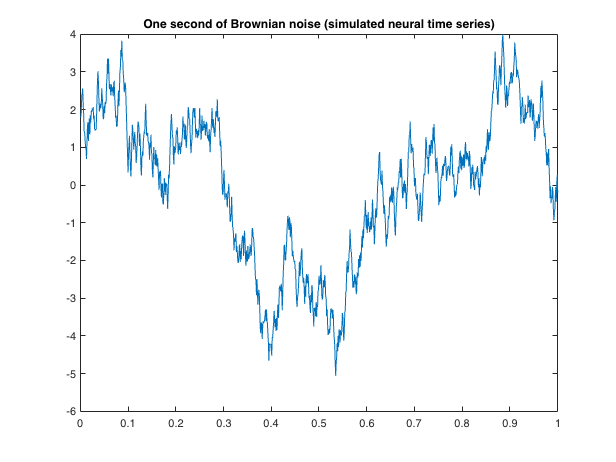

temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = detrend(cumsum(temp1));  % Brownian noise is the cumulative sum of white noise
figure
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 

Apply a bandpass filter and plot the data

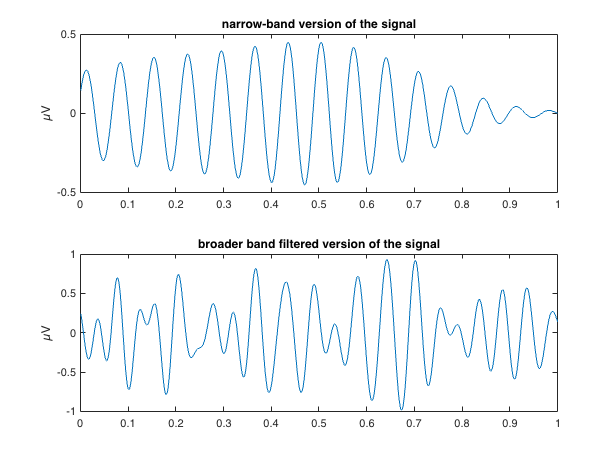

figure
y_narrow = bandpass(brownsig,[14 16],1000);
subplot(2,1,1), plot(time, y_narrow),title('narrow-band version of the signal') 
ylabel('µV')
y_broad = bandpass(brownsig,[14 25],1000);
subplot(2,1,2), plot(time, y_broad),title('broader band filtered version of the signal')
ylabel('µV')

Apply the Hilbert transform 

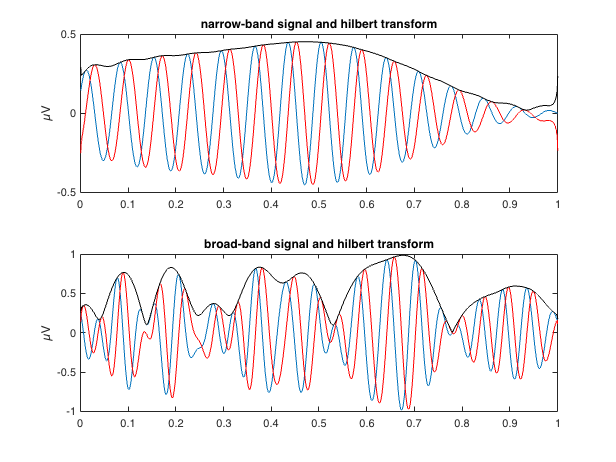

figure
H_narrow = hilbert(y_narrow); 
subplot(2,1,1), plot(time, y_narrow), ylabel('µV')
hold on, 
plot(time, imag(H_narrow), 'r'), title('narrow-band signal and hilbert transform'), ylabel('µV')
plot(time, abs(H_narrow), 'k')
hold off
H_broad = hilbert(y_broad); 
subplot(2,1,2), plot(time, y_broad), ylabel('µV')
hold on, 
plot(time, imag(H_broad), 'r'), title('broad-band signal and hilbert transform'), ylabel('µV')
plot(time, abs(H_broad), 'k')
hold off